clc
clear all


% Define constants
g = 9.81;          % (m/s^2)
M = 0.0844;        % (kg)
c = 7000;          % (N.m/A^2)
L = 0.115;         % (H)
R = 10;            % (ohm)
y_star = 0.002;    % (m)

% Calculate initial conditions
ue = sqrt(g * M * R^2 / c * (0.0072 - y_star));
xe1 = y_star;
xe2 = 0;
xe3 = ue / R;

% Define state-space matrices
f1x1 = 0;
f1x2 = 1;
f1x3 = 0;
f1u = 0;

f2x1 = (c / M) * (xe3)^2 / (0.0072 - xe1)^2;
f2x2 = 0;
f2x3 = (c / M) * 2 * (xe3) / (0.0072 - xe1);
f2u = 0;

f3x1 = 0;
f3x2 = 0;
f3x3 = -R / L;
f3u = 1 / L;

% State-space representation
A = [f1x1 f1x2 f1x3;
     f2x1 f2x2 f2x3;
     f3x1 f3x2 f3x3];
B = [f1u; f2u; f3u];
C = [1 0 0];
D = 0;

% Convert state-space to transfer function
[Plant_Num, Plant_Den] = ss2tf(A, B, C, D);
G = tf(Plant_Num, Plant_Den)

G =
 
               2.175e05
  ----------------------------------
  s^3 + 86.96 s^2 - 1887 s - 1.64e05
 
Continuous-time transfer function.
Model Properties



% Find zeros and poles
zeros1 = zero(G)


zeros1 =

  0×1 empty double column vector



poles = pole(G)

poles =    43.4343
  -86.9565
  -43.4343


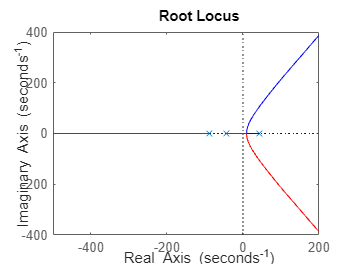


% Plot root locus
rlocus(G);

s= tf("s")

s =
 
  s
 
Continuous-time transfer function.
Model Properties


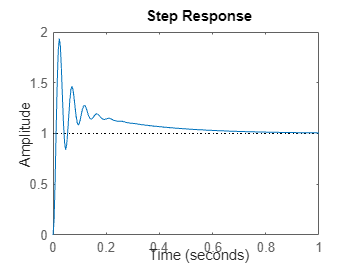


Gc = 370*(s+3)*(s+33)/(s*(s+3650));

step(feedback(Gc*G,1))

con_system_info = stepinfo(feedback(Gc*G,1))

con_system_info = struct with fields:
         RiseTime: 0.0080
    TransientTime: 0.7058
     SettlingTime: 0.7058
      SettlingMin: 0.8419
      SettlingMax: 1.9358
        Overshoot: 93.5818
       Undershoot: 0
             Peak: 1.9358
         PeakTime: 0.0237


file_name = 'Q2.slx';

PID1 = sim(file_name);
 % Calculate the step responses
y1 = PID1.nonlinear_con.Data;
t1 = PID1.nonlinear_con.Time;
stepinfo(y1)

ans = struct with fields:
         RiseTime: 16.5667
    TransientTime: 256.2058
     SettlingTime: 256.1924
      SettlingMin: 0.0018
      SettlingMax: 0.0038
        Overshoot: 90.5889
       Undershoot: 0
             Peak: 0.0038
         PeakTime: 167


Q3

Ts = [0.000001 0.00001 0.0001 0.001 0.01];
methods = {'matched', 'tustin'};

best_fit = struct('method', '', 'Ts', 0, 'error', Inf);

for method_idx = 1:length(methods)
    method = methods{method_idx};
    for i = 1:length(Ts)
        Gc_z = c2d(Gc, Ts(i), method);
        G_z = c2d(G, Ts(i), 'zoh');

        sys = feedback(Gc_z * G_z, 1);
        sys1 = feedback(Gc * G, 1);  % Assuming Gc and G are defined in the workspace

        % Calculate the step responses
        [y, t] = step(sys);
        [y1, t1] = step(sys1, t);  % Ensure same time vector for comparison

        % Compute the error (IAE or MSE)
        error = sum(abs(y - y1));  % IAE
        % error = mean((y - y1).^2);  % MSE (alternative)

        % Plot step response
        figure;
        step(sys);
        hold on;
        step(sys1);
        title(sprintf('Step Response: Method = %s, Ts = %.6f', method, Ts(i)));
        xlabel('Time (seconds)');
        ylabel('Amplitude');
        legend('Discretized System', 'Original System');

        % Save the figure
        filename = sprintf('StepResponse_%s_Ts%.6f.png', method, Ts(i));
        saveas(gcf, filename);

        fprintf('Method: %s, Ts: %.6f, Error: %.4f\n', method, Ts(i), error);

        % Check for best fit
        if error < best_fit.error
            best_fit.method = method;
            best_fit.Ts = Ts(i);
            best_fit.error = error;
        end

        % Close the figure
        close(gcf);
    end
end

Method: matched, Ts: 0.000001, Error: 307503330731426237770629120.0000
Method: matched, Ts: 0.000010, Error: 26848.3327
Method: matched, Ts: 0.000100, Error: 9.1451
Method: matched, Ts: 0.001000, Error: 18.7841
Method: matched, Ts: 0.010000, Error: 67599668209376297748529152.0000
Method: tustin, Ts: 0.000001, Error: 291321052075423164067217408.0000
Method: tustin, Ts: 0.000010, Error: 12342.7858
Method: tustin, Ts: 0.000100, Error: 8.4834
Method: tustin, Ts: 0.001000, Error: 10.7554
Method: tustin, Ts: 0.010000, Error: 77142645552691597298106368.0000



fprintf('Best fit: Method = %s, Ts = %.6f, Error = %.4f\n', best_fit.method, best_fit.Ts, best_fit.error);

Best fit: Method = tustin, Ts = 0.000100, Error = 8.4834


% file_name = 'Q3.slx';
% Ts = [0.00001 0.0001 0.001 0.01];
% methods = {'matched', 'tustin'};
% 
% best_fit = struct('method', '', 'Ts', 0, 'error', Inf);
% 
% for method_idx = 1:length(methods)
%     method = methods{method_idx};
%     for i = 1:length(Ts)
%         Gc_z = c2d(Gc, Ts(i), method);
% 
%         PID1 = sim(file_name);
% 
%         % Calculate the step responses
%         y = PID1.nonlinear.Data;
%         t = PID1.nonlinear.Time;
%         y1 = PID1.nonlinear_con.Data;
%         t1 = PID1.nonlinear_con.Time;
% 
%         % Compute the error (IAE or MSE)
%         error = sum(abs(y - y1));  % IAE
%         % error = mean((y - y1).^2);  % MSE (alternative)
% 
%         % Plot step response
%         figure;
%         plot(t, y, 'b', 'LineWidth', 1.5);
%         hold on;
%         plot(t1, y1, 'r--', 'LineWidth', 1.5);
%         title(sprintf('Step Response: Method = %s, Ts = %.6f', method, Ts(i)));
%         xlabel('Time (seconds)');
%         ylabel('Amplitude');
%         legend('Discretized System', 'Original System');
% 
%         % Save the figure
%         filename = sprintf('nonlinear_StepResponse_%s_Ts%.6f.png', method, Ts(i));
%         saveas(gcf, filename);
% 
%         fprintf('Method: %s, Ts: %.6f, Error: %.4f\n', method, Ts(i), error);
% 
%         % Check for best fit
%         if error < best_fit.error
%             best_fit.method = method;
%             best_fit.Ts = Ts(i);
%             best_fit.error = error;
%         end
% 
%         % Close the figure
%         close(gcf);
%     end
% end
% 
% fprintf('Best fit nonlinear: Method = %s, Ts = %.6f, Error = %.4f\n', best_fit.method, best_fit.Ts, best_fit.error);


Q4

best_fit_Ts = 0.0005 % we use best_fit_Ts from linear system

best_fit_Ts = 5.0000e-04

G_z = c2d(G,best_fit_Ts,'zoh')

G_z =
 
  4.483e-06 z^2 + 1.774e-05 z + 4.387e-06
  ---------------------------------------
    z^3 - 2.958 z^2 + 2.915 z - 0.9575
 
Sample time: 0.0005 seconds
Discrete-time transfer function.
Model Properties


poles_G_z = pole(G_z)

poles_G_z =     1.0220
    0.9785
    0.9575


zeros_G_z = zero(G_z)

zeros_G_z =    -3.6920
   -0.2650


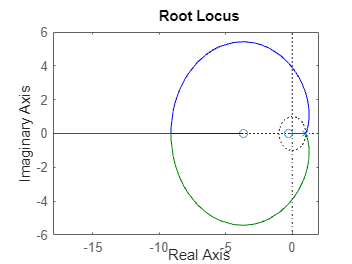

rlocus(G_z)

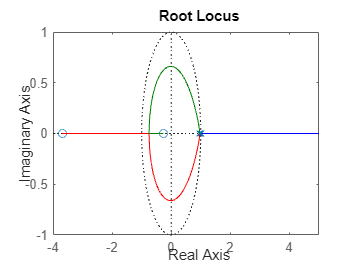

rlocus(-G_z)

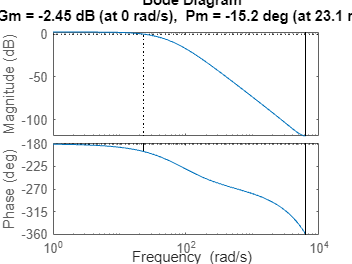


margin(G_z)

Q5

z = tf("z" , best_fit_Ts)

z =
 
  z
 
Sample time: 0.0005 seconds
Discrete-time transfer function.
Model Properties



Gc_z_designed = 550*(z- 0.9987)*(z-0.9892)/(z^2 - z)

Gc_z_designed =
 
  550 z^2 - 1093 z + 543.4
  ------------------------
          z^2 - z
 
Sample time: 0.0005 seconds
Discrete-time transfer function.
Model Properties


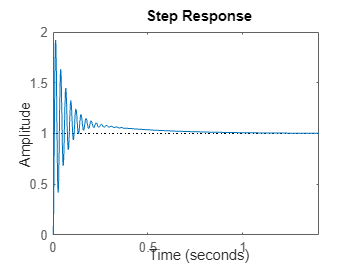

step(minreal(feedback(Gc_z_designed*G_z,1)))


stepinfo(minreal(feedback(Gc_z_designed*G_z,1)))

ans = struct with fields:
         RiseTime: 0.0045
    TransientTime: 0.7025
     SettlingTime: 0.7025
      SettlingMin: 0.4210
      SettlingMax: 1.9227
        Overshoot: 92.2683
       Undershoot: 0
             Peak: 1.9227
         PeakTime: 0.0135


file_name = 'Q5.slx';

PID1 = sim(file_name);
y1 = PID1.nonlinear.Data;
stepinfo(y1)

ans = struct with fields:
         RiseTime: 94.6917
    TransientTime: 2.8255e+03
     SettlingTime: 2.8253e+03
      SettlingMin: 0.0016
      SettlingMax: 0.0020
        Overshoot: 1.3987e-10
       Undershoot: 0
             Peak: 0.0020
         PeakTime: 19851


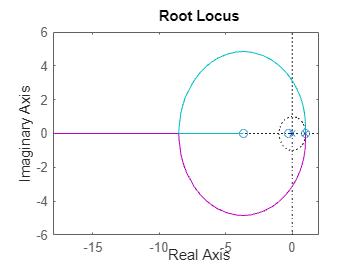

rlocus(Gc_z_designed*G_z)

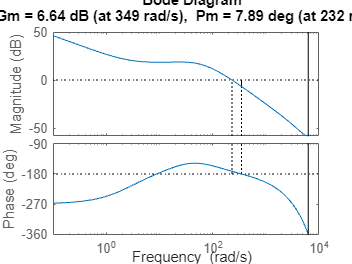

margin(Gc_z_designed*G_z)

Q7


% Find the zeros and poles of the transfer function
zeros_Gz = zero(G_z);
poles_Gz = pole(G_z);

% Identify zeros and poles outside the unit circle
alpha = zeros_Gz(abs(zeros_Gz) > 1);
beta = poles_Gz(abs(poles_Gz) > 1);

% Desired characteristic
f4 = -0.7;

% Create the matrix for solving coefficients
A2 = [1, 1, 1; alpha^3, alpha^2, alpha; beta^3, beta^2, beta];
b = [1 - f4; -f4; beta^4 - f4];

% Solve for the coefficients f1, f2, and f3
f = A2 \ b

f =     0.4197
    1.5327
   -0.2524



% Define the controller F(z)
F = f(1)*z^(-1) + f(2)*z^(-2) + f(3)*z^(-3) + f4*z^(-4)

F =
 
  0.4197 z^9 + 1.533 z^8 - 0.2524 z^7 - 0.7 z^6
  ---------------------------------------------
                      z^10
 
Sample time: 0.0005 seconds
Discrete-time transfer function.
Model Properties



% Calculate the controller Gc_db and closed-loop system Gcl_db
Gc_db = minreal(F / (1 - F) * 1 / G_z)

Gc_db =
 
  9.362e04 z^4 - 1.85e05 z^3 + 5.277e04 z^2 + 7.832e04 z - 3.962e04
  -----------------------------------------------------------------
          z^4 + 0.8672 z^3 - 0.7576 z^2 - 0.9281 z - 0.1815
 
Sample time: 0.0005 seconds
Discrete-time transfer function.
Model Properties


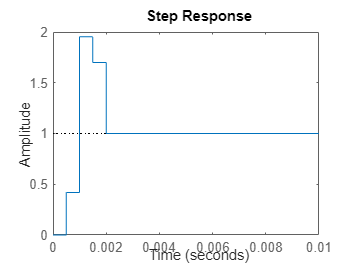

Gcl_db = minreal(feedback(Gc_db * G_z, 1));

% Plot the step response of the closed-loop system
step(Gcl_db);


stepinfo(Gcl_db)

ans = struct with fields:
         RiseTime: 5.0000e-04
    TransientTime: 0.0020
     SettlingTime: 0.0020
      SettlingMin: 1.0000
      SettlingMax: 1.9524
        Overshoot: 95.2421
       Undershoot: 0
             Peak: 1.9524
         PeakTime: 1.0000e-03


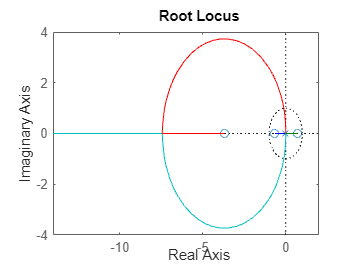

rlocus(Gcl_db)

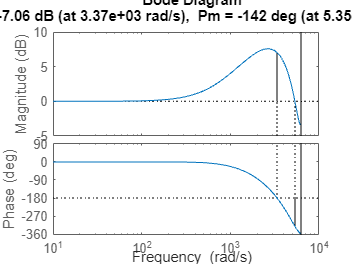

margin(Gcl_db)

file_name = 'Q7.slx';

PID1 = sim(file_name);
y1 = PID1.nonlinear.Data;
stepinfo(y1)

ans = struct with fields:
         RiseTime: 0
    TransientTime: 298.0374
     SettlingTime: 293.5705
      SettlingMin: 1.0000e-05
      SettlingMax: 1.4328e-05
        Overshoot: 43.2813
       Undershoot: 0
             Peak: 1.4328e-05
         PeakTime: 104


Q8

Gc_z1 = c2d(Gc, best_fit_Ts, 'tustin');
Gc_z2 = c2d(Gc, best_fit_Ts, 'matched');

Q9

z = tf("z" , best_fit_Ts);


G = expm(A*best_fit_Ts)

G =     1.0002    0.0005    0.0031
    0.9433    1.0002   12.2416
         0         0    0.9575


syms x
H = double(int(expm(A*x)*B, x, [0 best_fit_Ts]))

H =     0.0000
    0.0268
    0.0043



rank(ctrb(G,H))

ans = 3


rank(obsv(G,C))

ans = 3

Q10

% Extract the Denominator values from the system G and store in 'a'
a = poly(G);
a = a(2:end);

% Construct matrix W using elements of 'a'
W = [a(2) a(1) 1; 
     a(1) 1 0; 
     1 0 0];
Tinv = inv(ctrb(G, H) * W);

% Initialize alpha for Dead beat control design
alpha = zeros(1, 3);

% Calculate the feedback gain 'k'
k = flip(alpha - a) * Tinv

k = 1.0e+04 *

    3.7611    0.0038    0.0419


P = inv(C*inv(eye(3) - (G-H*k))*H);


Q11

G_prime = G.';
H_prime = C.';
Tinv = inv(ctrb(G_prime, H_prime)*W);

alpha = [0, 0.1, 0.01];
L = flip(alpha - a)*Tinv

L = 1.0e+03 *

    0.0030    4.9380    0.1642
